# Experiment with TCNpathToEEG model

## Load data

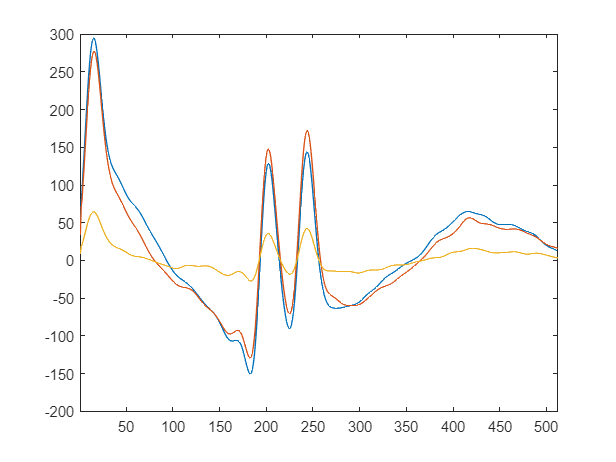

XTrain = load(fullfile('DataSet','HyperparameterSearch','Train','XSearchTrain.mat')).XSearchTrain;
YTrain = load(fullfile('DataSet','HyperparameterSearch','Train','YSearchTrain.mat')).YSearchTrain;

XTest = load(fullfile('DataSet','HyperparameterSearch','Test','XSearchTest.mat')).XSearchTest;
YTest = load(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat')).YSearchTest;

trainDs = {XTrain, YTrain};
testDs = {XTest, YTest};

figure;i = 1;
plot(XTrain{i}');
xlim([1 size(XTrain{i},2)]);

## Hyper-parameter search

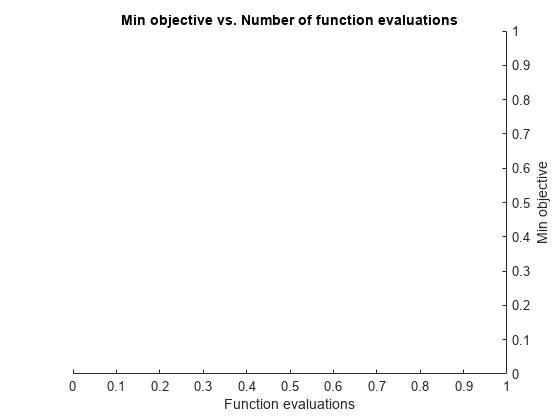

|=================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |   numFilters |   filterSize |    numBlocks | dropoutFactor| miniBatchSize| learningrate |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |
|=================================================================================================================================================================|
|    1 | Best   |    0.076336 |      260.54 |    0.076336 |    0.076336 |           32 |           25 |            4 |      0.10581 |          114 |    0.0001945 |
|    2 | Best   |     0.07559 |      146.95 |     0.07559 |     0.07559 |            4 |           33 |            2 |     0.011192 |           87 |       0.0048 |
|    3 | Best   

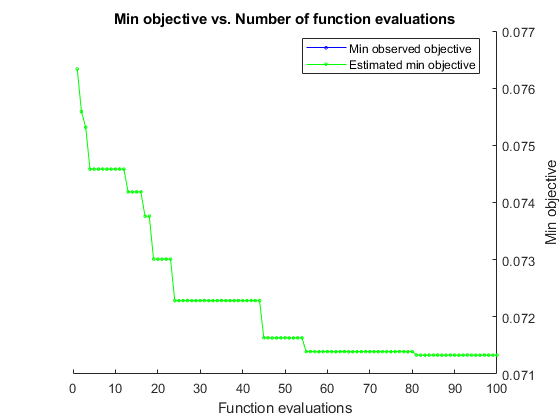


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 30986.0782 seconds
Total objective function evaluation time: 30942.6617

Best observed feasible point:
    numFilters    filterSize    numBlocks    dropoutFactor    miniBatchSize    learningrate
    __________    __________    _________    _____________    _____________    ____________

        32            13            2          0.0089237           127          0.0038137  

Observed objective function value = 0.071331
Estimated objective function value = 0.071331
Function evaluation time = 170.8176

Best estimated feasible point (according to models):
    numFilters    filterSize

maxEpochs = 30;
optimVars = [
    %numFilters, filterSize, numBlocks, dropoutFactor
    optimizableVariable('numFilters',[2 32],'Type','integer')
    optimizableVariable('filterSize',[3 33],'Type','integer')
    optimizableVariable('numBlocks',[1 5],'Type','integer')
    optimizableVariable('dropoutFactor',[0.00 0.2],'Type','real')
    optimizableVariable('miniBatchSize',[8 128],'Type','integer')    
    optimizableVariable('learningrate',[1e-4 1e-1],'Type','real',"Transform","log")];

objectFunction = objectFunctionTCN(trainDs, testDs,  maxEpochs);
    
% optimizer
BayesObject = bayesopt( objectFunction,             optimVars, ...
                        'MaxTime',                  24*60*60, ...
                        'Verbose',                  1,...
                        "UseParallel",              false,...
                        'IsObjectiveDeterministic', true, ...
                        'ParallelMethod',           "clipped-model-prediction",...
                        'MaxObjectiveEvaluations',  100,...
                        'ExplorationRatio',         0.6,...
                        'AcquisitionFunctionName', 'expected-improvement-per-second-plus');

optVars = bestPoint(BayesObject);

save("HyperParameterSearch\OptVars\CovMixoptVars.mat","optVars","-mat");

    % Evaluate and train the network with the optimal parameters
[valError,~,net, YPred, YTest] = BayesObject.ObjectiveFcn(optVars,1);

TX = {};
for k = 1:numel(testDs)
    TX{end+1} = testDs{k}{1};
end


TY = [];
Y = [];
YTest = YTest.';
for k = 1:numel(testDs{1})
    TY = [TY;YTest{k}];
    Y = [Y;YPred{k}];
end

Undefined variable 'YPred'.


confusionchart(TY(:),Y(:),'Normalization','column-normalized');